%计算考虑化学作用后的三锁体系
clear all
syms e r o l k;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
for l=3.2:0.025:4.2
    for k = 0:0.1:2
        t=1-1/(1+exp((5000*k)/(8.31*298)))
%计算锁死所占成分
        fun1 = @(x1,x2) P(x1).^(2*k).*P(x2-x1).^(2*k).*P(l-x2).^(k);
        x2min= @(x1) x1;
        V_lock = 3*integral2(fun1,0,l,x2min,l);

%计算开放所占成分
        fun2 = @(x1,x2) P(l-x2).^(k).*P(x2).^k.*P(x2-x1).^k.*P(l-x1).^k.*P(x1).^k;
        x2min= @(x1) x1;
        V_open = 2*integral2(fun2,0,l,x2min,l);
        P_lock = V_lock/(V_lock + V_open); %计算锁死所占比例
        Plock=[Plock,(1-(t^3)*P_lock)/(1-t)]
    end
end

t = 0.5000

Plock = 1.8500

t = 0.5503

Plock =     1.8500    2.0009


t = 0.5996

Plock =     1.8500    2.0009    2.1355


t = 0.6470

Plock =     1.8500    2.0009    2.1355    2.2652


t = 0.6916

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861


t = 0.7329

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954


t = 0.7706

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915


t = 0.8043

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741


t = 0.8341

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462


t = 0.8602

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976


t = 0.8828

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369


t = 0.9021

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664


t = 0.9186

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881


t = 0.9324

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036


t = 0.9441

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144


t = 0.9539

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216


t = 0.9620

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261


t = 0.9687

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685


t = 0.9743

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771


t = 0.9789

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838


t = 0.9827

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889


t = 0.5000

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500


t = 0.5503

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989


t = 0.5996

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313


t = 0.6470

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581


t = 0.6916

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755


t = 0.7329

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812


t = 0.7706

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740


t = 0.8043

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538


t = 0.8341

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707


t = 0.8828

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086


t = 0.9021

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375


t = 0.9186

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593


t = 0.9324

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755


t = 0.9441

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874


t = 0.9539

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959


t = 0.9620

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019


t = 0.9687

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060


t = 0.9743

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087


t = 0.9789

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741


t = 0.9827

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800


t = 0.5000

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500


t = 0.5503

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973


t = 0.5996

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279


t = 0.6470

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279    2.2524


t = 0.6916

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279    2.2524    2.3674


t = 0.7329

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279    2.2524    2.3674    2.4705


t = 0.7706

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279    2.2524    2.3674    2.4705    2.5611


t = 0.8043

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279    2.2524    2.3674    2.4705    2.5611    2.6391


t = 0.8341

Plock =     1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213    2.8707    2.9086    2.9375    2.9593    2.9755    2.9874    2.9959    3.0019    3.0060    3.0087    2.9741    2.9800    1.8500    1.9973    2.1279    2.2524    2.3674    2.4705    2.5611    2.6391


t = 0.8602

Plock = 1×52
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×53
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×54
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×55
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×56
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×57
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×58
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×59
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×60
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×61
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×62
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×63
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×64
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×65
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×66
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×67
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×68
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×69
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×70
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×71
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×72
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×73
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×74
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×75
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×76
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×77
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×78
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×79
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×80
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×81
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×82
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×83
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×84
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×85
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×86
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×87
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×88
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×89
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×90
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×91
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×92
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×93
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×94
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×95
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×96
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×97
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×98
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×99
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×100
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×101
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×102
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×103
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×104
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×105
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×106
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×107
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×108
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×109
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×110
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×111
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×112
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×113
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×114
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×115
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×116
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×117
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×118
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×119
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×120
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×121
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×122
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×123
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×124
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×125
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×126
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×127
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×128
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×129
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×130
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×131
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×132
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×133
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×134
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×135
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×136
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×137
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×138
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×139
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×140
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×141
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×142
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×143
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×144
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×145
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×146
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×147
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×148
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×149
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×150
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×151
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×152
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×153
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×154
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×155
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×156
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×157
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×158
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×159
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×160
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×161
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×162
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×163
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×164
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×165
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×166
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×167
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×168
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×169
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×170
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×171
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×172
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×173
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×174
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×175
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×176
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×177
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×178
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×179
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×180
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×181
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×182
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×183
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×184
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×185
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×186
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×187
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×188
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×189
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×190
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×191
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×192
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×193
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×194
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×195
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×196
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×197
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×198
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×199
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×200
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×201
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×202
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×203
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×204
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×205
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×206
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×207
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×208
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×209
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×210
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×211
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×212
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×213
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×214
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×215
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×216
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×217
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×218
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×219
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×220
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×221
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×222
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×223
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×224
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×225
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×226
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×227
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×228
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×229
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×230
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×231
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×232
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×233
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×234
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×235
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×236
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×237
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×238
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×239
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×240
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×241
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×242
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×243
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×244
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×245
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×246
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×247
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×248
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×249
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×250
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×251
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×252
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×253
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×254
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×255
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×256
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×257
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×258
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×259
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×260
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×261
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×262
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×263
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×264
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×265
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×266
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×267
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×268
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×269
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×270
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×271
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×272
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×273
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×274
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×275
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×276
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×277
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×278
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×279
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×280
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×281
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×282
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×283
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×284
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×285
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×286
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×287
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×288
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×289
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×290
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×291
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×292
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×293
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×294
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×295
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×296
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×297
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×298
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×299
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×300
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×301
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×302
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×303
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×304
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×305
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×306
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×307
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×308
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×309
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×310
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×311
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×312
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×313
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×314
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×315
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×316
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×317
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×318
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×319
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×320
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×321
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×322
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×323
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×324
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×325
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×326
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×327
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×328
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×329
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×330
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×331
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×332
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×333
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×334
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×335
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×336
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×337
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×338
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×339
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×340
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×341
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×342
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×343
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×344
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×345
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×346
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×347
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×348
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×349
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×350
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×351
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×352
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×353
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×354
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×355
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×356
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×357
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×358
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×359
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×360
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×361
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×362
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×363
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×364
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×365
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×366
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×367
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×368
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×369
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×370
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×371
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×372
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×373
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×374
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×375
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×376
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×377
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×378
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×379
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×380
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×381
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×382
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×383
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×384
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×385
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×386
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×387
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×388
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×389
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×390
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×391
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×392
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×393
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×394
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×395
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×396
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×397
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×398
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×399
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×400
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×401
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×402
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×403
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×404
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×405
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×406
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×407
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×408
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×409
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×410
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×411
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×412
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×413
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×414
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×415
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×416
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×417
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×418
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×419
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×420
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×421
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×422
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×423
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×424
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×425
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×426
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×427
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×428
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×429
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×430
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×431
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×432
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×433
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×434
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×435
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×436
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×437
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×438
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×439
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×440
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×441
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×442
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×443
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×444
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×445
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×446
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×447
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×448
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×449
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×450
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×451
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×452
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×453
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×454
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×455
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×456
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×457
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×458
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×459
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×460
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×461
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×462
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×463
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×464
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×465
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×466
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×467
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×468
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×469
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×470
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×471
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×472
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×473
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×474
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×475
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×476
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×477
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×478
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×479
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×480
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×481
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×482
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×483
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×484
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×485
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×486
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×487
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×488
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×489
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×490
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×491
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×492
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×493
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×494
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×495
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×496
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×497
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×498
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×499
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×500
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×501
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×502
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×503
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×504
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×505
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×506
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×507
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×508
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×509
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×510
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×511
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×512
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×513
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×514
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×515
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×516
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×517
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×518
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×519
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×520
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×521
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×522
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×523
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×524
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×525
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×526
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×527
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×528
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×529
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×530
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×531
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×532
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×533
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×534
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×535
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×536
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×537
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×538
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×539
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×540
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×541
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×542
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×543
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×544
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×545
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×546
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×547
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×548
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×549
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×550
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×551
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×552
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×553
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×554
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×555
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×556
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×557
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×558
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×559
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×560
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×561
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×562
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×563
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×564
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×565
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×566
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×567
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×568
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×569
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×570
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×571
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×572
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×573
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×574
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×575
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×576
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×577
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×578
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×579
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×580
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×581
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×582
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×583
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×584
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×585
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×586
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×587
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×588
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×589
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×590
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×591
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×592
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×593
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×594
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×595
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×596
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×597
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×598
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×599
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×600
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×601
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×602
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×603
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×604
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×605
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×606
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×607
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×608
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×609
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×610
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×611
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×612
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×613
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×614
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×615
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×616
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×617
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×618
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×619
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×620
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×621
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×622
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×623
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×624
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×625
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×626
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×627
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×628
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×629
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×630
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×631
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×632
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×633
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×634
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×635
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×636
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×637
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×638
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×639
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×640
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×641
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×642
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×643
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×644
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×645
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×646
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×647
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×648
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×649
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×650
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×651
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×652
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×653
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×654
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×655
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×656
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×657
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×658
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×659
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×660
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×661
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×662
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×663
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×664
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×665
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×666
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×667
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×668
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×669
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×670
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×671
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×672
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×673
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×674
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×675
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×676
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×677
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×678
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×679
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×680
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×681
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×682
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×683
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×684
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×685
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×686
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×687
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×688
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×689
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×690
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×691
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×692
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×693
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×694
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×695
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×696
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×697
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×698
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×699
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×700
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×701
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×702
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×703
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×704
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×705
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×706
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×707
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×708
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×709
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×710
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×711
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×712
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×713
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×714
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×715
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×716
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×717
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×718
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×719
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×720
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×721
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×722
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×723
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×724
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×725
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×726
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×727
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×728
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×729
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×730
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×731
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×732
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×733
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×734
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×735
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×736
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×737
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×738
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×739
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×740
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×741
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×742
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×743
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×744
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×745
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×746
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×747
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×748
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×749
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×750
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×751
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×752
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×753
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×754
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×755
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×756
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×757
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×758
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×759
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×760
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×761
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×762
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×763
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×764
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×765
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×766
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×767
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×768
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×769
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×770
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×771
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×772
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×773
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×774
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×775
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×776
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×777
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×778
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×779
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×780
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×781
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×782
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×783
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×784
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×785
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×786
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×787
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×788
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×789
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×790
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×791
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×792
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×793
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×794
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×795
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×796
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×797
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×798
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×799
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×800
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×801
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×802
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×803
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×804
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×805
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×806
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×807
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×808
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×809
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×810
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×811
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×812
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×813
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×814
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×815
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×816
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×817
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×818
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×819
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×820
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×821
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×822
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×823
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×824
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×825
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×826
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×827
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×828
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×829
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×830
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×831
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×832
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×833
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×834
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×835
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×836
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×837
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×838
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×839
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×840
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5000

Plock = 1×841
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5503

Plock = 1×842
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.5996

Plock = 1×843
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6470

Plock = 1×844
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.6916

Plock = 1×845
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7329

Plock = 1×846
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.7706

Plock = 1×847
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8043

Plock = 1×848
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8341

Plock = 1×849
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8602

Plock = 1×850
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.8828

Plock = 1×851
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9021

Plock = 1×852
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9186

Plock = 1×853
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9324

Plock = 1×854
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9441

Plock = 1×855
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9539

Plock = 1×856
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9620

Plock = 1×857
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9687

Plock = 1×858
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9743

Plock = 1×859
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9789

Plock = 1×860
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


t = 0.9827

Plock = 1×861
    1.8500    2.0009    2.1355    2.2652    2.3861    2.4954    2.5915    2.6741    2.8462    2.8976    2.9369    2.9664    2.9881    3.0036    3.0144    3.0216    3.0261    2.9685    2.9771    2.9838    2.9889    1.8500    1.9989    2.1313    2.2581    2.3755    2.4812    2.5740    2.6538    2.7213


    
l=3:0.025:4;
k=0:0.5:10;
[L,K]=meshgrid(l,k);
Z=reshape(Plock,[21 41])

Z = 21×41
    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500    1.8500
    2.0009    1.9989    1.9973    1.9958    1.9946    1.9936    1.9927    1.9920    1.9914    1.9909    1.9905    1.9901    1.9898    1.9896    1.9894    1.9892    1.9891    1.9890    1.9890    1.9890    1.9889    1.9889    1.9890    1.9890    1.9890    1.9891    1.9891    1.9892    1.9893    1.9893
    2.1355    2.1313    2.1279    2.1252    2.1230    2.1212    2.1199    2.1188    2.1181    2.1176    2.1173    2.1171    2.1171    2.1172    2.1174    2.1177    2.1180    2.1184    2.1188    2.1193    2.1198    2.1203    2.1208    2.1214    2.1219    2.1224    2.1230    2.1235    2.1241    2.1246
    2.2652    2.2581    2.2524    2.2480    2.2446    2.2421    2.2403    2.2390    2.2

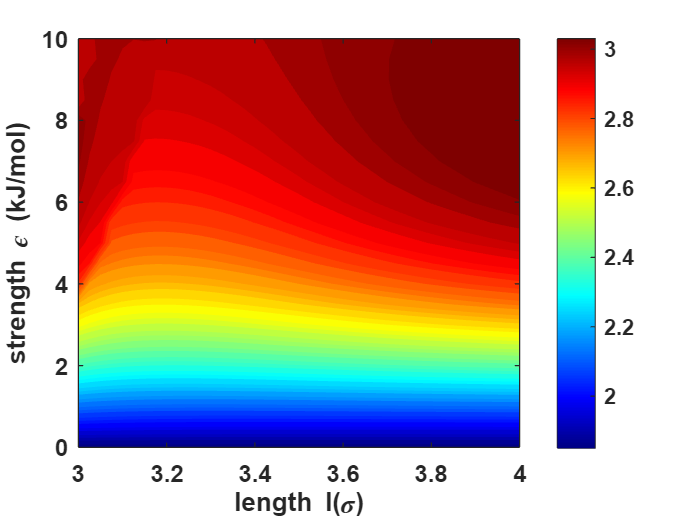

[C,h]=contourf(L,K,Z,50,'--','ShowText','off','LabelSpacing',1000);
h.LevelList=round(h.LevelList,2);  %等高线数值保留小数点后两位
set(h, 'edgecolor','none');
clabel(C,h);

colorbar;
colormap("jet");

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('strength \epsilon (kJ/mol)','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5000;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end
